### load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

con_list = dir(fullfile(mount_dir, '*/con_0017.nii'));
spm('Defaults','fMRI')
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0017.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25558272 bytes
Loading image number:    64
Elapsed time is 5.337298 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6155290  Bit rate: 22.55 bits


### `check data coverage`

drawnow; snapnow
m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display;

SPM12: spm_check_registration (v7759)              12:59:30 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


drawnow; snapnow
plot(con_data_obj)

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 43.75%
Expected 3.20 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 5 images		Cases 4 14 27 41 50 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 40.62%
Expected 3.20 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 11 34 
Uncorrected: 6 images		Cases 11 13 34 51 53 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                          

SPM12: spm_check_registration (v7759)              12:59:39 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


ans = 64×1 logical array
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0


### run robfit

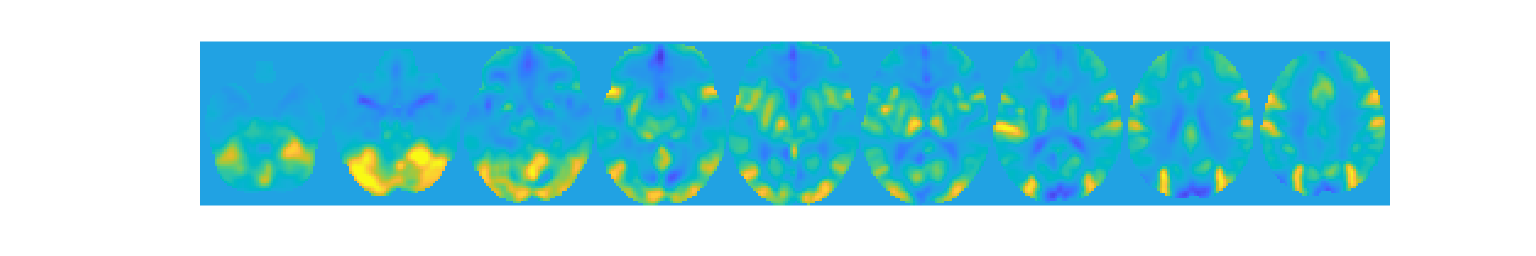

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat
Initializing nodes to match regions.
Updating node response data.
Updating obj.connectivity.nodes.
Updating obj.connectivity.nodes.
Updating region averages.
Updating obj.connectivity.regions.
Updating obj.connectivity.regions.
__________________________________________________________________
Input image diagnostic information
__________________________________________________________________
Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 40.62%
Expected 3.20 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 11 34 
Uncorrected: 6 images		Cases 6 11 34 53 60 62 

Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 32.81%
Expected 3.20 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		

    48



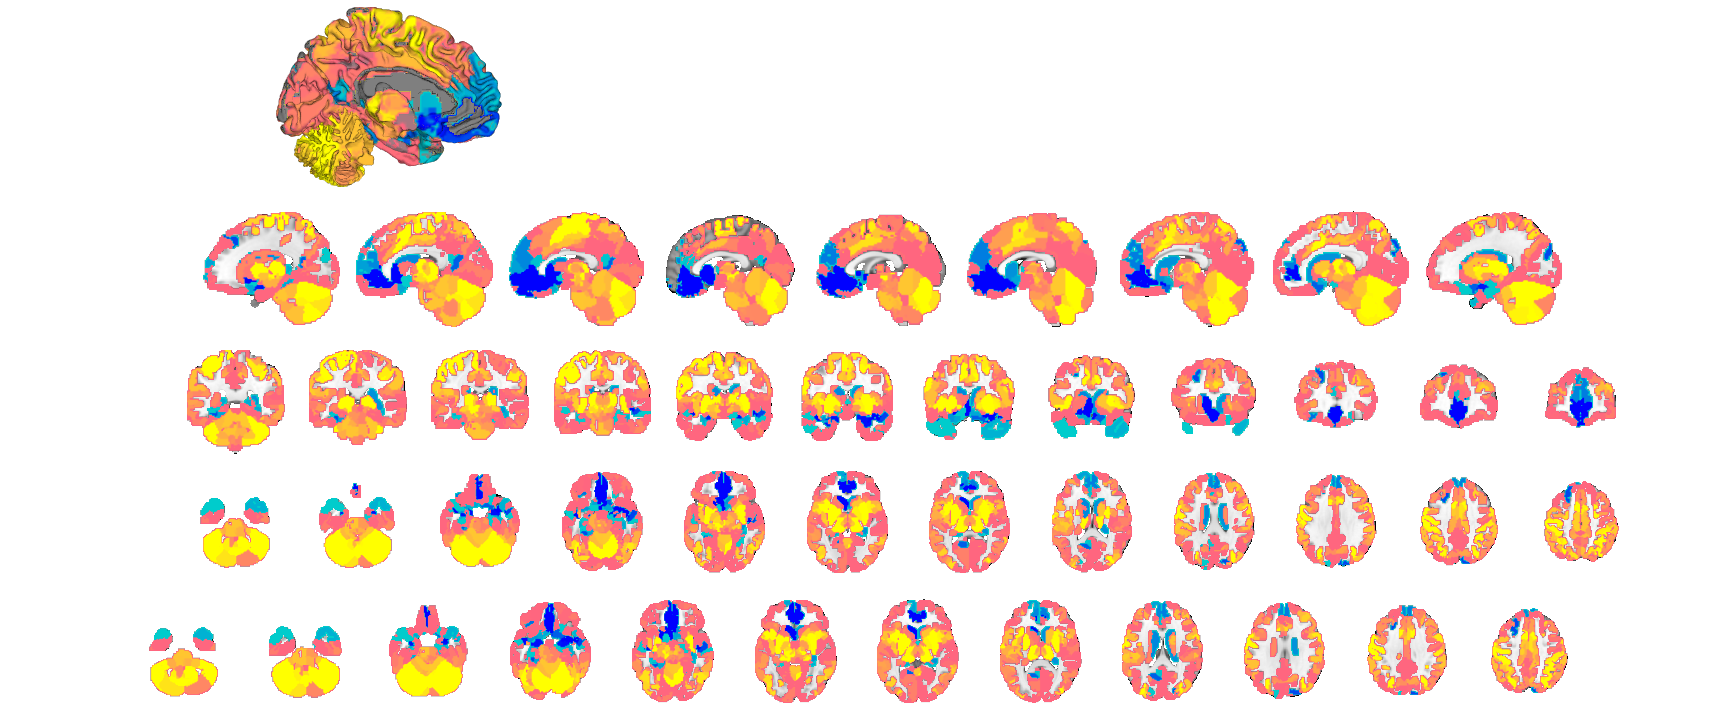

____________________________________________________________________________________________________________________________________________
Positive Effects


sampleto = '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask.nii'

           Region             Volume             XYZ            maxZ       modal_label_descriptions       Perc_covered_by_label    Atlas_regions_covered    region_index
    ____________________    __________    _________________    ______    _____________________________    _____________________    _____________________    ____________

    {'Cau_L'           }             8    -16     14    -12    7.0345    {'Basal_ganglia'            }             100                        0                  3      
    {'Multiple regions'}    1.2225e+06     -2    -34      0    7.0345    {'Cerebellum'               }               2                      433                  1      
    {'Ctx_AAIC_R'      }             8     28      

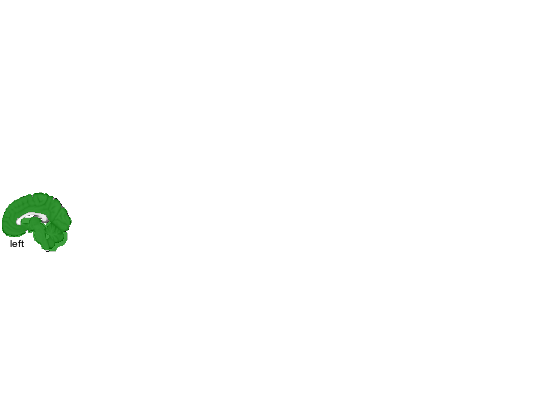

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 32.81%
Expected 3.20 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 11 34 
Uncorrected: 7 images		Cases 1 11 13 34 51 60 62 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 40.62%
Expected 3.20 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 11 34 
Uncorrected: 6 images		Cases 6 11 34 53 60 62 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                

SPM12: spm_check_registration (v7759)              13:01:05 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

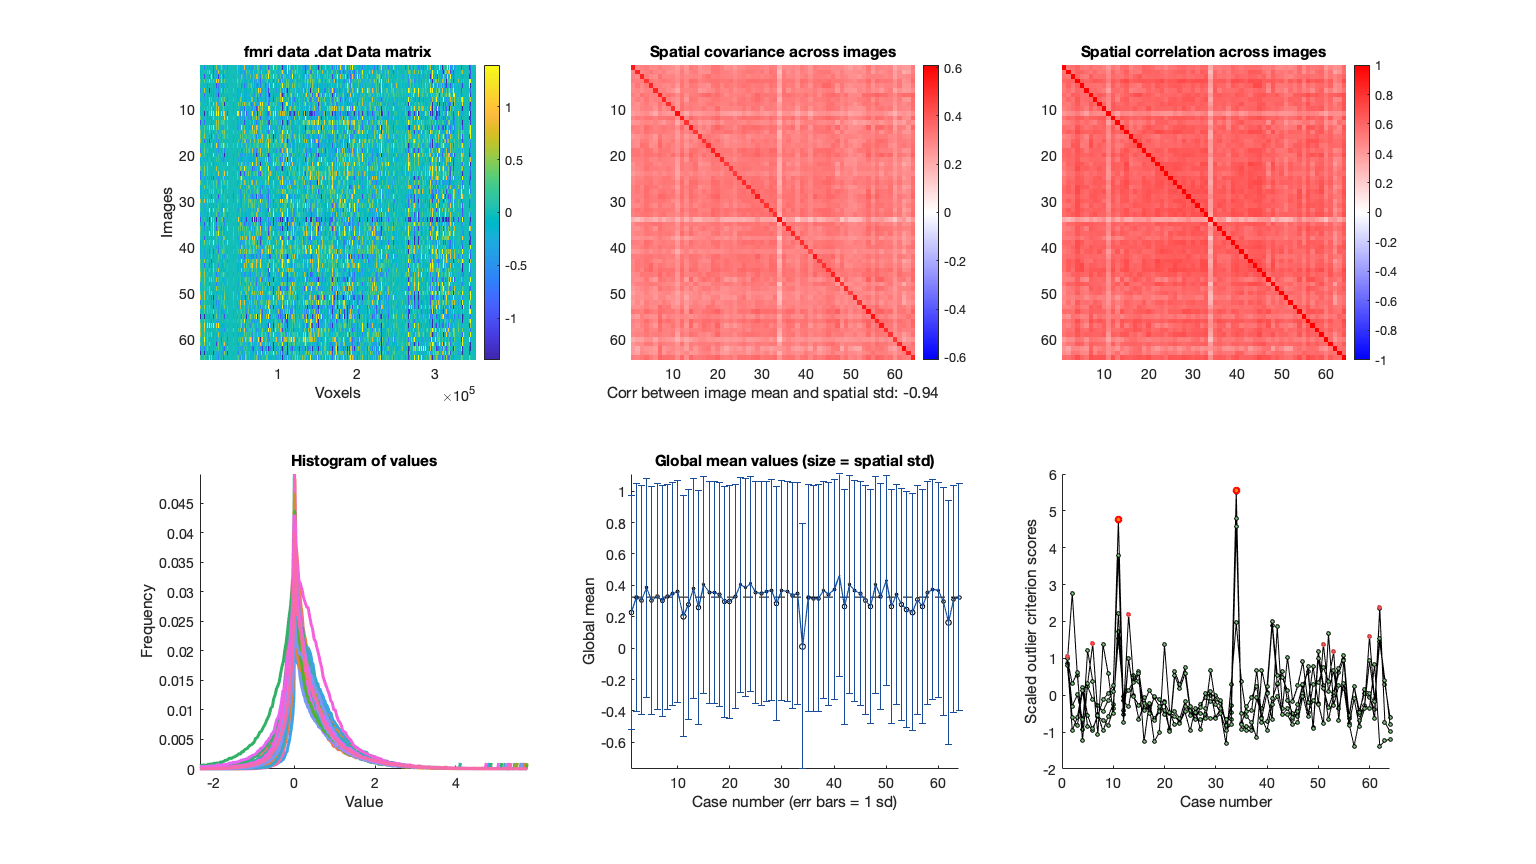

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


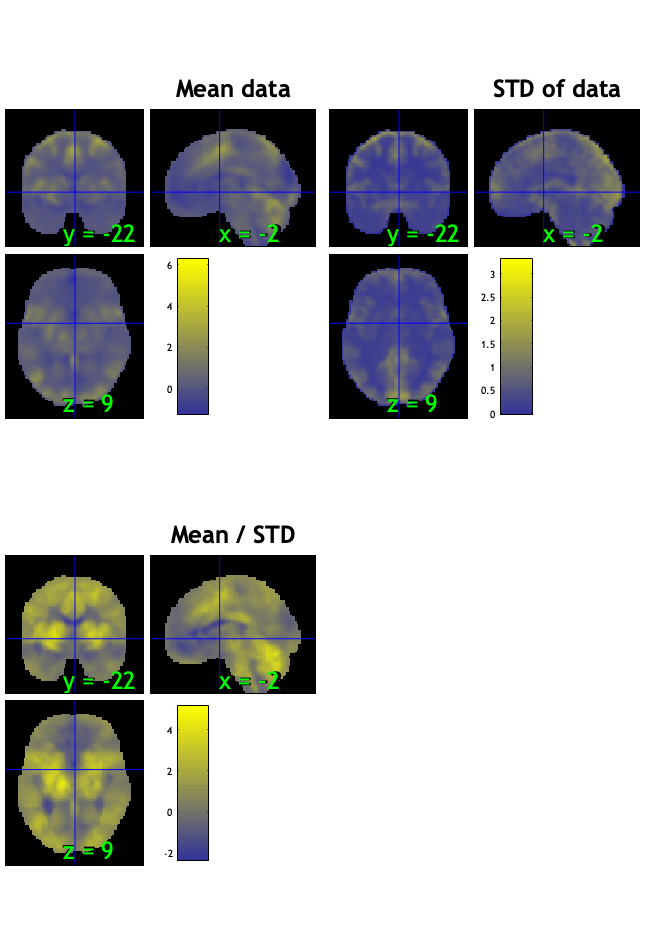

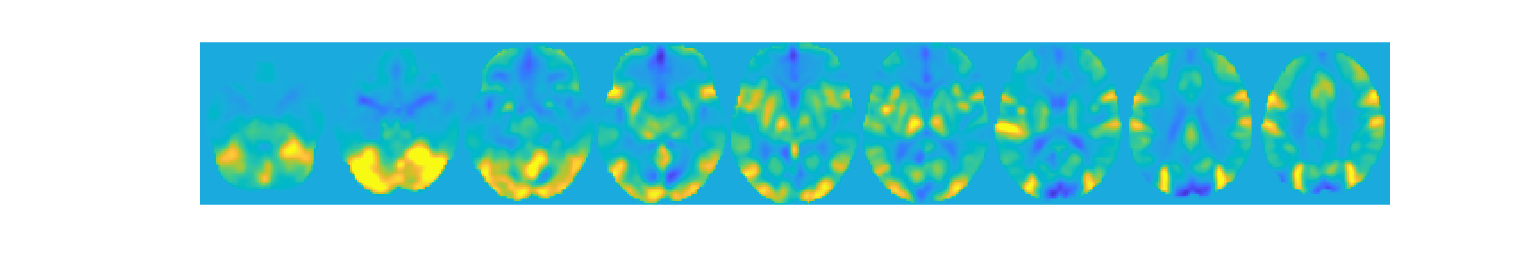

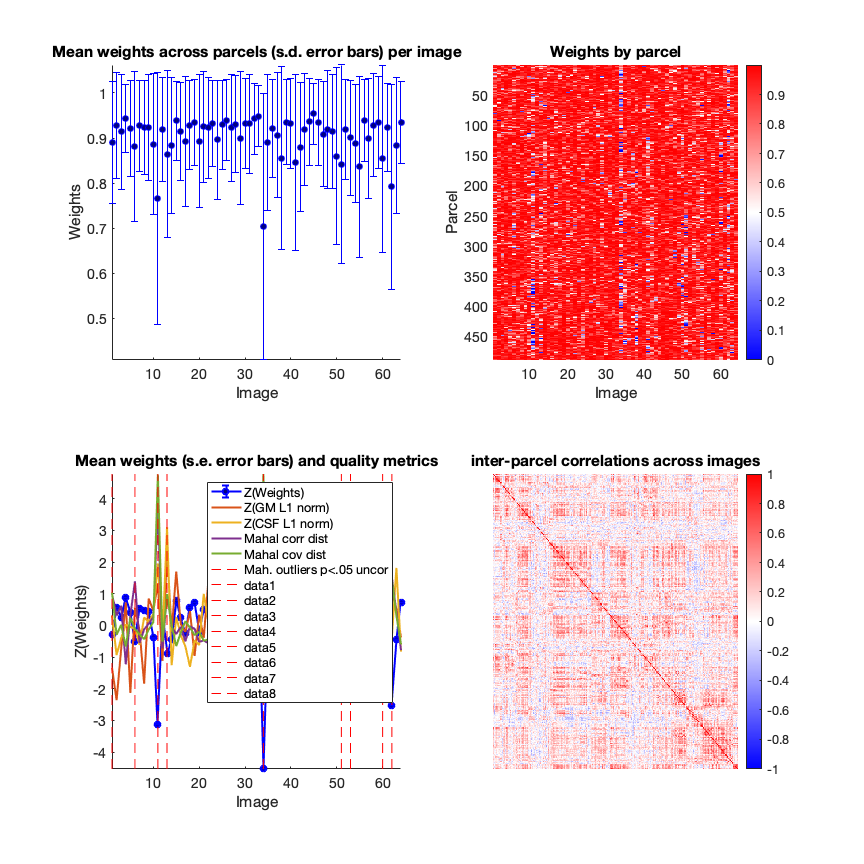

set(gcf,'Visible','on')
figure ('Visible', 'on');
imgs2 = con_data_obj.rescale('l2norm_images');
out = robfit_parcelwise(imgs2);


drawnow, snapnow;


adsf

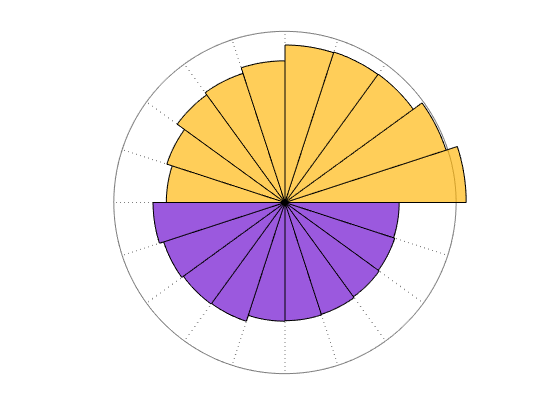

r_low = top_feature_tables{1}.testr_low;
r_high = top_feature_tables{1}.testr_high;

r_to_plot = [r_high; r_low];
textlabels = [ highwords lowwords]';
create_figure('wedge_plot');
hh = tor_wedge_plot(r_to_plot, textlabels, 'outer_circle_radius', .3, 'colors', {[1 .7 0] [.4 0 .8]}, 'bicolor', 'nofigure');

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( con_data_obj, 'images_are_replicates', false, 'noverbose');

Input image 1
./fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0017.nii
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.23123     {'trait'     }     0.31767      {'movements'   }
    -0.22346     {'age'       }     0.29693      {'hand'        }
    -0.22005     {'negative'  }     0.27801      {'execution'   }
     -0.2189     {'positive'  }     0.27729      {'motor'       }
    -0.20807     {'affect'    }     0.27603      {'finger'      }
    -0.20717     {'emotion'   }     0.24832      {'hands'       }
    -0.20607     {'person'    }     0.23797      {'visual'      }
    -0.20423     {'depression'}      0.2334      {'sensorimotor'}
    -0.20227     {'rating'    }     0.21764      {

lowwords = [top_feature_tables{1}.words_low(:)]';
disp(lowwords)

  Columns 1 through 7

    {'trait'}    {'age'}    {'negative'}    {'positive'}    {'affect'}    {'emotion'}    {'person'}

  Columns 8 through 10

    {'depression'}    {'rating'}    {'affective'}




highwords = [top_feature_tables{1}.words_high(:)]';
disp(highwords)

  Columns 1 through 7

    {'movements'}    {'hand'}    {'execution'}    {'motor'}    {'finger'}    {'hands'}    {'visual'}

  Columns 8 through 10

    {'sensorimotor'}    {'action'}    {'preparation'}




r_low = top_feature_tables{1}.testr_low;
r_high = top_feature_tables{1}.testr_high;

r_to_plot = [r_high; r_low];
textlabels = [ highwords lowwords];


%%

create_figure('wedge_plot');

%hh = tor_wedge_plot(r_to_plot, textlabels, 'outer_circle_radius', .3, 'colors', {[1 .7 0] [.4 0 .8]}, 'nofigure');

hh = tor_wedge_plot(r_to_plot, textlabels, 'outer_circle_radius', .3, 'colors', {[1 .7 0] [.4 0 .8]}, 'bicolor', 'nofigure');